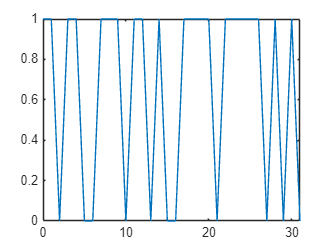

clc, clear, close all
sps = 4;                % Количество выборок на символ
M = 16;                 % Глубина модуляции
k = log2(M);            % Кол-во битов на символ
EbNoVec = (1:11);       % величина Eb/No (dB)
numSymPerFrame = 2^3;  % Кол-во КАМ символов в кадре
rng default
dataIn = randi([0 1],numSymPerFrame*k,1);
t = (0:31);
time = transpose(t);
plot(time,dataIn)

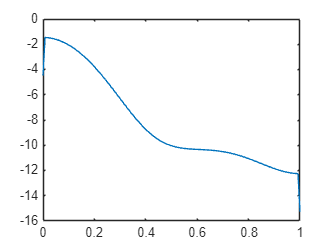

[px,w] = pwelch(dataIn);
plot(w/pi,10*log10(px))

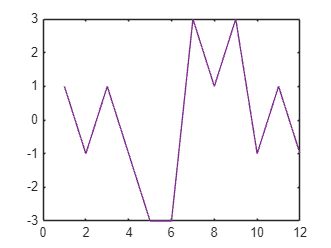

        
        % ПРИМЕНЕНИЕ СВЕРТОЧНОГО КОДА:

        constrlen = [5 4];           % Длина кодового ограничения
        genpoly = [23 35 0; 0 5 13]; % Создание Полиномов

        tPoly = poly2trellis(constrlen,genpoly); %Определение решетки сверточного кодирования 
        
                                                 % Определенная решетка представляет собой сверточный код, который функция convenc 
                                                 % использует для кодирования двоичного вектора dataIn.
        
        % КОДИРОВАНИЕ ВХОДНЫХ ДАННЫХ:

        dataEnc = convenc(dataIn,tPoly);
        dataSym = bit2int(dataEnc,k);
        
        % КАМ модуляция 
        txSig = qammod(dataSym,M);
        %t = (0:11);
        %time2 = transpose(t);
        %plot(time2,txSig)
        %[px,w] = pwelch(txSig);
        %plot(w/pi,10*log10(px))


        % ПРОХОЖДЕНИЕ ЧЕРЕЗ СМЕСИТЕЛЬ
        
        fg = 2400*10^6;           % Частота гетеродина [Гц]
        fs = 7*10^3;              %Частота дискретизации
        txSigUp = txSig * cos(2*pi*fg*t);

        plot(1:12,txSigUp)

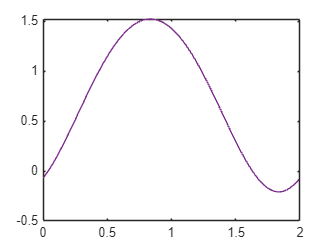

        [px,w] = pwelch(txSigUp);
        plot(w/pi,10*log10(px))

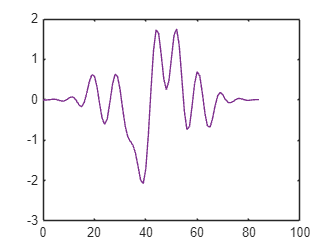


        % СОЗДАНИЕ ФИЛЬТРА ПРИПОДНЯТОГО КОСИНУСА:
        filtlen = 10; %Длина фильтра в символах
        rolloff = 0.25; %Коэффициент затухания фильтра
        rrcFilter = rcosdesign(rolloff,filtlen,sps); % функция для создания фильтра Прип.Кос.
        txSignal = upfirdn(txSigUp,rrcFilter,sps,1);
        t = (0:84);
        time = transpose(t);
        plot(time,txSignal)

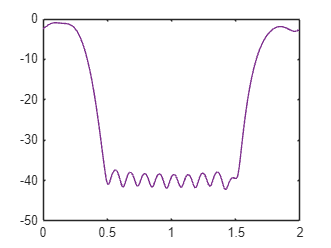

        [px,w] = pwelch(txSignal);
        plot(w/pi,10*log10(px))